soft_folder = "soft_gripper_expts_2/";
soft_files = ["expt_2.mat";"expt_3.mat";"expt_5.mat";"expt_6.mat";"expt_10.mat"];

rigid_folder = "rigid_gripper_expts_2/";
rigid_files = ["expt_1.mat";"expt_2.mat";"expt_8.mat";"expt_9.mat";"expt_10.mat"];

% plot variables here
titlefsz = 20;
textfsz = 17;
axfsz = 15;
linewidth = 2;

load("characteristic_2.mat");
k = k/2;
r = r/2;

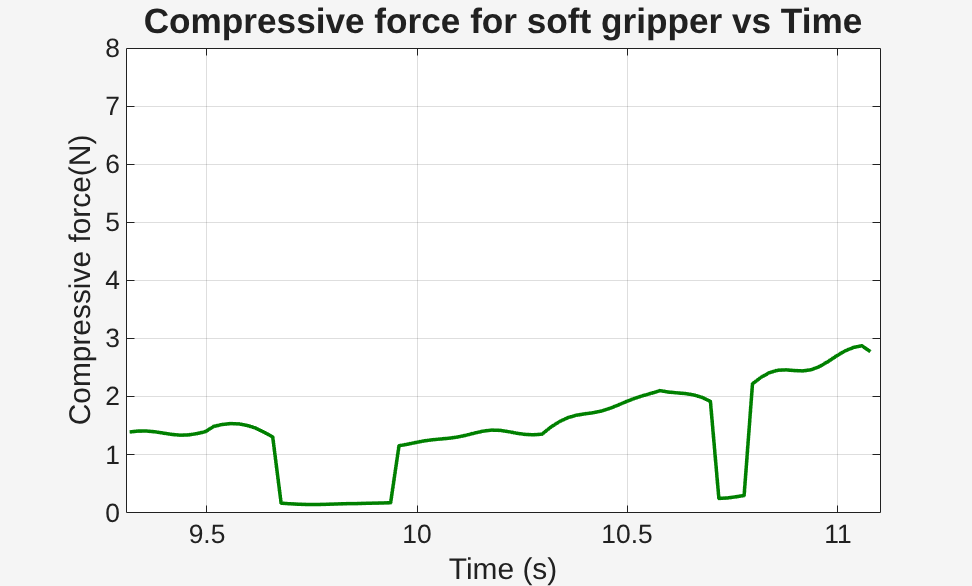

figure;
theme(figure,"light");

for i = 1:1
    % plot the soft gripper net deformation
    load(soft_folder + soft_files(i));
    fz_left = -1*estimate_lattice_force(enc(:,1),ot,t_inv,k,r(1),r(2),kr);
    plot(ot(i1:i2),fz_left(i1:i2),"Color",[0 0.5 0],"LineWidth",linewidth);
    hold on;
end

ax = gca;
ax.FontSize = axfsz;
xlabel("Time (s)","FontSize",textfsz);
ylabel("Compressive force(N)","FontSize",textfsz);
title("Compressive force for soft gripper vs Time","FontSize",titlefsz);
xlim([9.31,11.1]);
ylim([0,8]);
grid on;
%legend(["Soft gripper","Rigid Gripper"]);
saveas(gcf,"soft_compressive_force.png");
hold off;

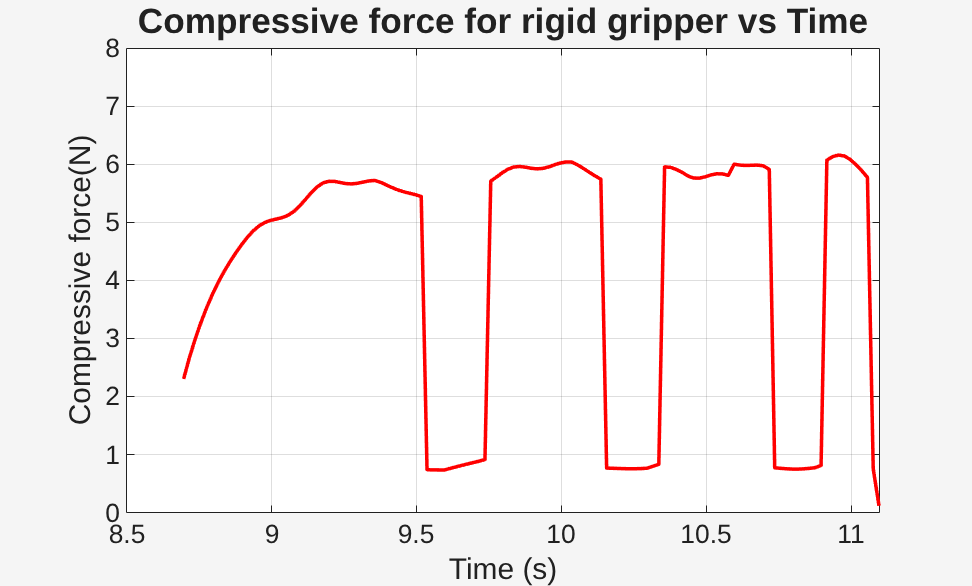



figure;
theme(figure,"light");

for i = 1:1
    % plot the rigid gripper net deformation
    load(rigid_folder + rigid_files(i));
    fz_left = -1*estimate_lattice_force(enc(:,1),ot,t_inv,k,r(1),r(2),kr);
    %fz_left = lowpass(fz_left,0.9);
    plot(ot(i1:i2),fz_left(i1:i2),"Color",[1 0 0],"LineWidth",linewidth);
    hold on;
end

ax = gca;
ax.FontSize = axfsz;
xlabel("Time (s)","FontSize",textfsz);
ylabel("Compressive force(N)","FontSize",textfsz);
title("Compressive force for rigid gripper vs Time","FontSize",titlefsz);
xlim([8.5,11.1]);
ylim([0,8]);
grid on;
%legend(["Soft gripper","Rigid Gripper"]);
saveas(gcf,"rigid_compressive_force.png");
hold off;

% plot(at,net_area',"LineWidth",linewidth,"Color",[0 0.5 0]);
% hold on;
% ax = gca;
% ax.FontSize = axfsz;
% xlabel('Time (s)','FontSize',textfsz);
% ylabel('Net Area (m^2)','FontSize',textfsz);
% title('Contact Area vs time','FontSize',titlefsz-2);
% xlim([0 25]);
% grid on;
% saveas(gcf,"Contact area over full experiment.png")
% hold off;
